clc
close all

sig = 0.15;
m1 = 0; m2 = 0; mo = [m1 m2]';

Y = @(t,m) (m(1).*exp(m(2).*t));
t = [1 2 4 5 8]';
y = [3.2939 4.2699 7.1749 9.3008 20.259]';

max_iter = 1e6;
tol = 1e-6;

warning('off','all')

%generate roughening matrices
n =2;
L0 = eye(n);
 

ans =      0
     0
     0
     0
     0


### N0.1  Report the resulting parameter estimates, the number of iterations it took to converge until the norm of the change in parameter estimates was less than 10`−`6, and calculate the χ2obs and p-values. 

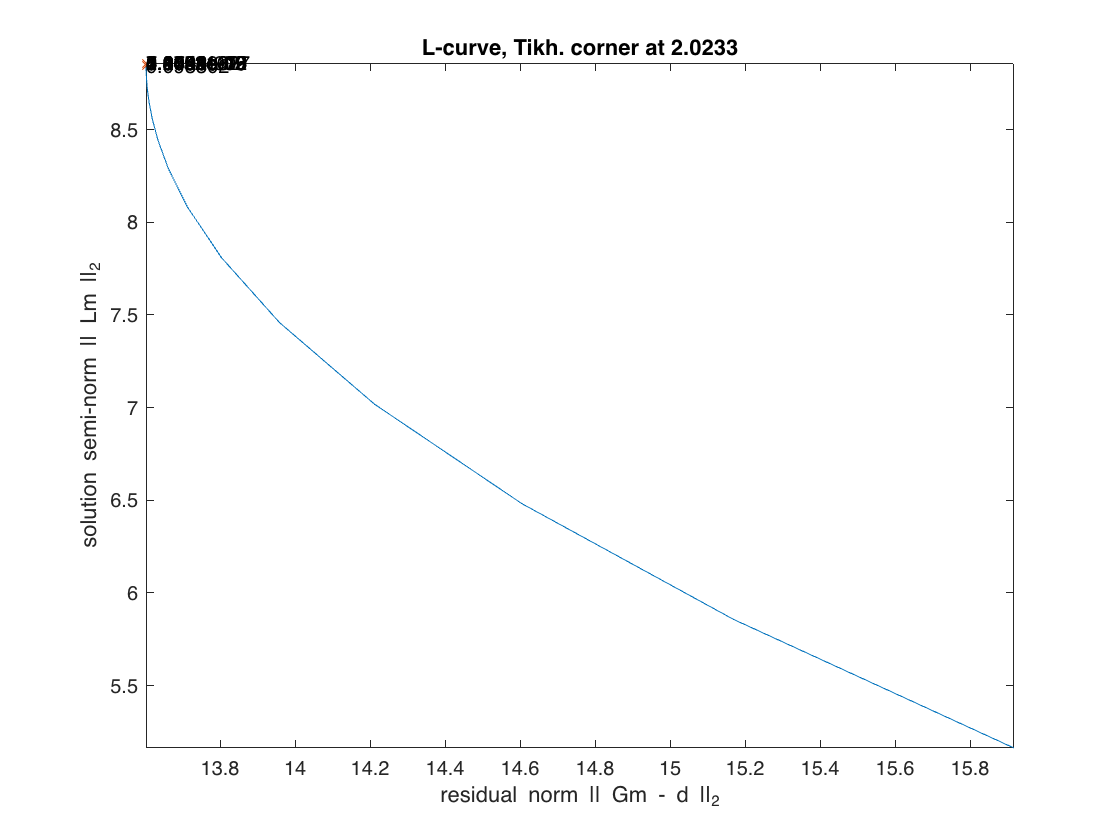

J = @(t,m) [(exp(m(2)*t)), (m(1)*t.*exp(m(2)*t))]; %exact jacobian

[U,sm,X,V,W] = cgsvd(J(t,mo),L0);

%regtools
[reg_corner,rho,eta,reg_param] = l_curve(U,sm,y,'Tikh');

alpha = reg_corner;
disp(['The resulting value of alpha = ',num2str(alpha)]);

The resulting value of alpha = 2.0233


for k = 1:max_iter
    dm = inv(J(t,mo)'*J(t,mo) + (alpha^2).*L0'*L0)*J(t,mo)'*(y-Y(t,mo));
    m = mo + dm;
    if norm(m-mo) < tol
        fprintf('Number of iterations taken = %d',k);
        break   
    end
    mo = m;   
end

Number of iterations taken = 16

disp(['Resulting parameter estimates are [',num2str(m'),']']);

Resulting parameter estimates are [2.5411      0.2595]


%chi-square
chi_s = 0;
for i = 1:length(t)
    chi_s = chi_s + ((Y(t(i),m)-y(i)))^2;   
end

disp(['chi-square obs = ',num2str(chi_s)])

chi-square obs = 6.4847e-09


The value of the $\chi_{obs}^{2}$ is much less than the expected value (m-n = 3), hence we reject the null hypothesis.

% pvalue
p = 1 - chi2cdf(chi_s,5);
disp(['pvalue   = ',num2str(p)])

pvalue   = 1


Since the value of the p-value is 1, then we reject the null hypothesis as already confirmed by the $\chi_{obs}^{2}$, since the fit of the model predictions to the data is almost exact, which is not realistic hence, the parameter estimates are not good.

### Discuss the advantages and disadvantages of using nonlinear inversion as compared to nonlinear regression.

Nonlinear inversion are computationally expensive compared to nonlinear regression since it takes nonlinear inversion almost twice the number of iterations it takes nonlinear regression to converge to the solution given the same initial estimates. 

The value of $\alpha$ used in nonlinaer inversion influences the solution to a larger extent, and most times the methods used to obtain it might not give as the best solution, and this affects the computational cost of the method, while in nonlinear regression the value of lamba is chosen best on how accurate and fast the solution is obtained.

### N0.2

m1 =0; m2 = 0; mo = [m1 m2]';

K = 10;
rho = []; eta = []; 
rrh=[]; al = []; 
est = [];

for alpha = logspace(-2,2,20)
    for k = 1:K
      dm = -inv(J(t,mo)'*J(t,mo) + (alpha^2).*L0'*L0)*(J(t,mo)'*(Y(t,mo) - y) + (alpha^2).*L0'*L0*mo);
      m = mo + dm;
      if norm(m-mo) < tol
        est = [est m];
        break   
      end
      mo = m;  
    end
    al = [al alpha];
    rho = [rho norm(Y(t,m) - y)];
    res = [rho norm(Y(t,m) - y)^2];
    rrh =[rrh norm(Y(t,m) - y)^2 + norm(m)^2];
    eta = [eta norm(L0*m)];
   
end

fprintf('Number of iterations taken = %d',k);

Number of iterations taken = 4

M = [est(k-1);est(k)];
disp(['Resulting parameter estimates are [',num2str(M'),']']);

Resulting parameter estimates are [2.541     0.25951]


### For the final value for k, plot the L-curve and discuss its shape.

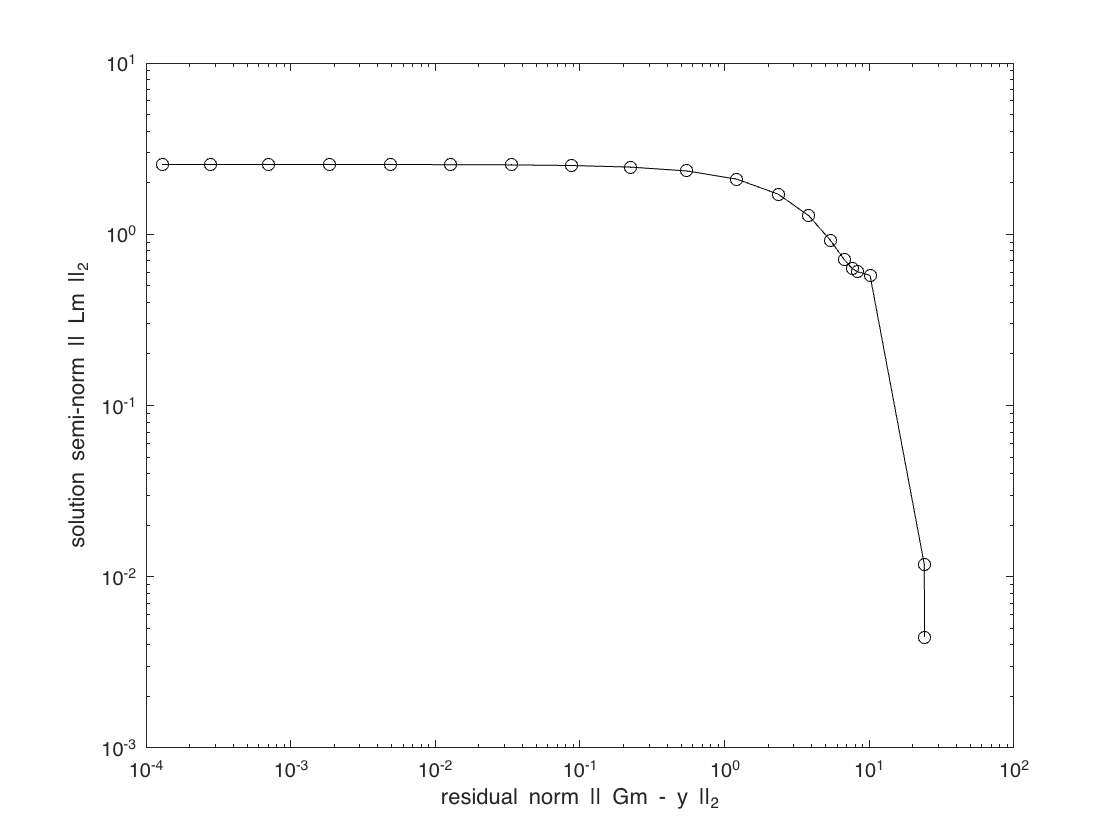

figure(1)
loglog(rho,eta,'ok-')
ylabel('solution semi-norm || Lm ||_2')
xlabel('residual norm || Gm - y ||_2')

The shape and smoothnes of the L-curve depends on the domain in which $\alpha$ is picked from, for the first values of alpha, the solution converges, since $\alpha$ increase with increase in iterations, hence therefore starting at $\alpha = 10^0$, the curve drops due to large values of $\alpha$ that give as very bad estimates. This decreasing motonic behaviour yields the L-curve shape.

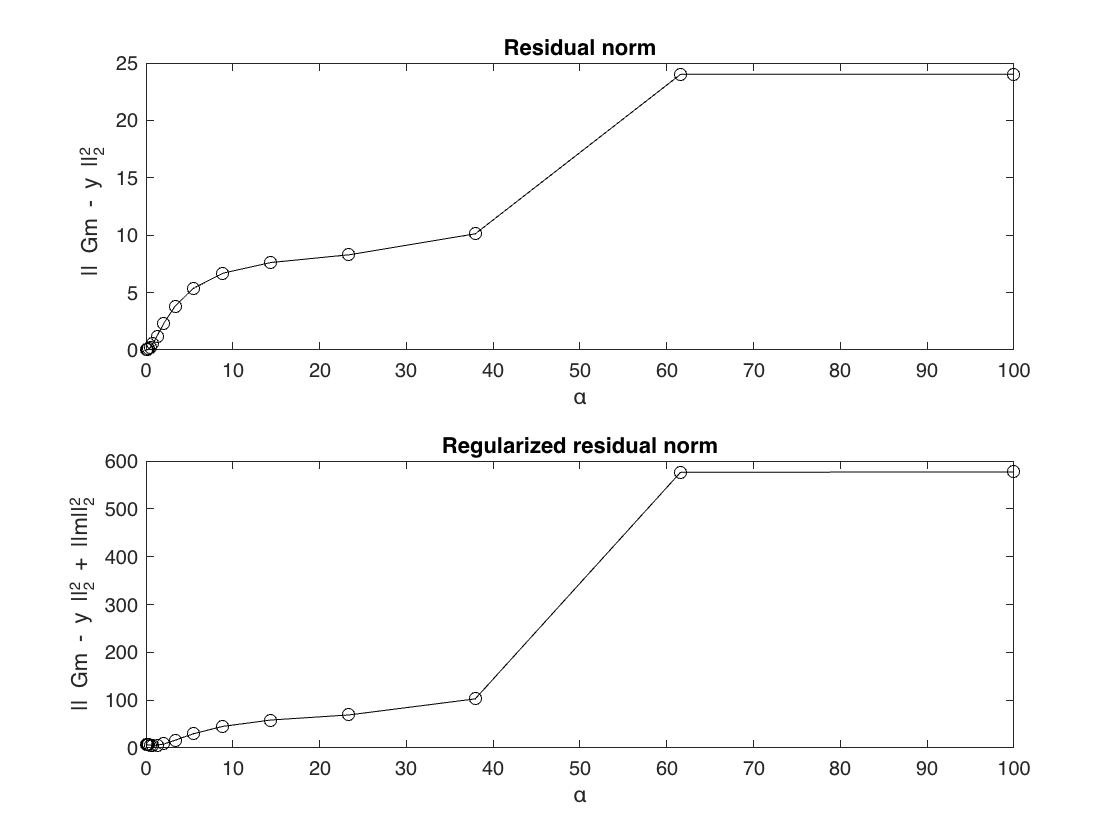

figure(3)
subplot(2,1,1)
plot(al,res(1:end-1),'ok-')
xlabel('\alpha')
ylabel('|| Gm - y ||_2^2 ')
title('Residual norm')

subplot(2,1,2)
plot(al,rrh,'ok-')
xlabel('\alpha')
ylabel('|| Gm - y ||_2^2 + ||m||_2^2')
title('Regularized residual norm')

The residual and the regularized residual are monotonically increasing up to the $\alpha = 60$, and then becomes constant, however the regularized residual increases gradually compared to the residual. Basing on that i will choose $\alpha$ using the regularized residula norm.

###  N0.3 Occam's inversion algorithm

m1 =0; m2 = 0; mo = [m1 m2]';
M = []; R_alp = [];
K=15; m = 5; n = 2;
delta = (m-n)*sig^2;
alphas = logspace(-2,0.5,K);

for k = 1:K
    chi = [];
    dcap = y - Y(t,mo) + J(t,mo)*mo;
    for alpha = alphas
      mk = inv(J(t,mo)' * J(t,mo) + (alpha^2) .* L0' * L0) * J(t,mo)' * dcap ;
      chii = norm(Y(t,mk) - y)^2;
      chi = [chi chii];
    end

    [Y1,idx] = min(chi); R_alp = [R_alp Y1];
    
    if (Y1 > delta^2)
        alpha = alphas(idx(1));
    else
        idx = find(chi <= delta^2);
        alpha = alphas(max(idx));
    end
    

    mo = inv(J(t,mo)' * J(t,mo) + (alpha^2) .* L0' * L0) * J(t,mo)' * dcap;
    M = [M mo];
end

Resulting_estimates = M 

Resulting_estimates =     8.8595   -0.0828    2.5408    1.0664    1.3280    1.7098    2.2591    2.5260    2.5284    2.5284    2.5284    2.5284    2.5284    2.5284    2.5284
         0    0.2570    0.1797    0.3715    0.3412    0.3074    0.2697    0.2596    0.2602    0.2602    0.2602    0.2602    0.2602    0.2602    0.2602


Resulting_alpha = R_alp

Resulting_alpha =   185.0216  615.1018  105.1053   19.6445   12.6012    5.8219    1.4125    0.0176    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


As $\alpha$ decreases, the corresponding first and second parameters are inversely correlated for the first $8$ iterations and then stabilize when $\alpha$ becomes constant.